# **CA#1 **

## **Name: Sogol Goodarzi **

## **SID: 810198467**

# **Part 1 **

## **1.1) **

### 
$$x_1 \left\lbrack n\right\rbrack ={\left(0\ldotp 8\right)}^n \;\;\;\;\;\;\;\;\;\;-10\le n\le 20$$


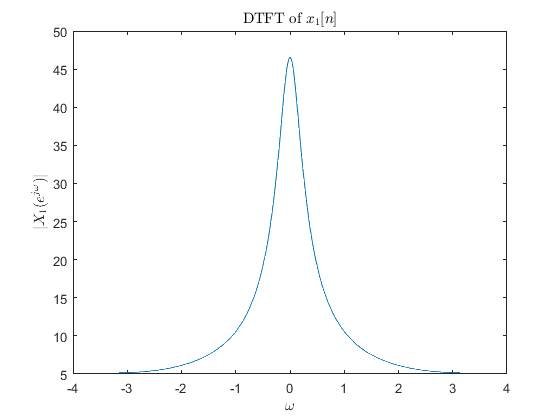

w=-pi:0.01:pi;
n1=-10:1:20;
x1=0.8.^n1;
X1=DTFT(x1,n1,w);
plot(w,abs(X1));
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$|X_1(e^{j\omega})|$','Interpreter','latex')
title ('DTFT of $x_1[n]$','Interpreter','latex')

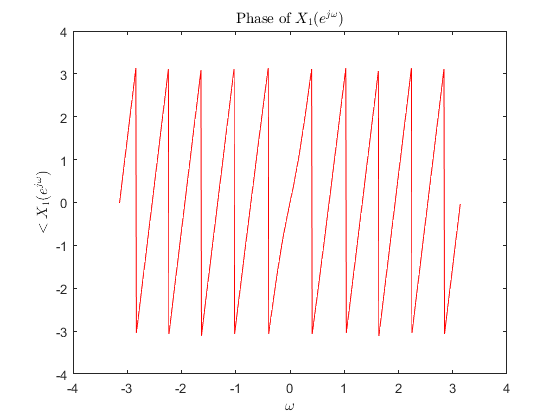

plot(w,angle(X1),'r');
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$<X_1(e^{j\omega})$','Interpreter','latex')
title ('Phase of $X_1(e^{j\omega})$','Interpreter','latex')

### 
$$x_2 \left\lbrack n\right\rbrack =1\;\;\;\;\;\;\;\;\;0\le n\le 40$$


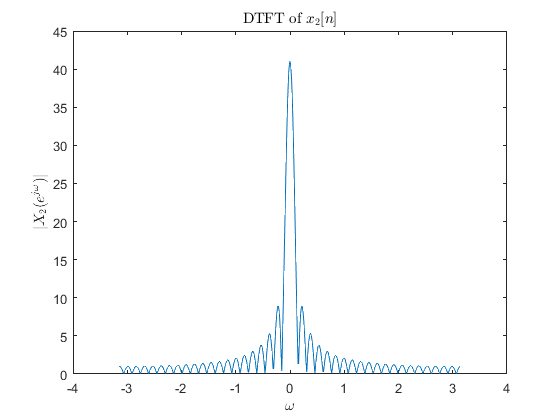

n2=0:1:40;
x2=ones(1,41);
X2=DTFT(x2,n2,w);
plot(w,abs(X2));
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$|X_2(e^{j\omega})|$','Interpreter','latex')
title ('DTFT of $x_2[n]$','Interpreter','latex')

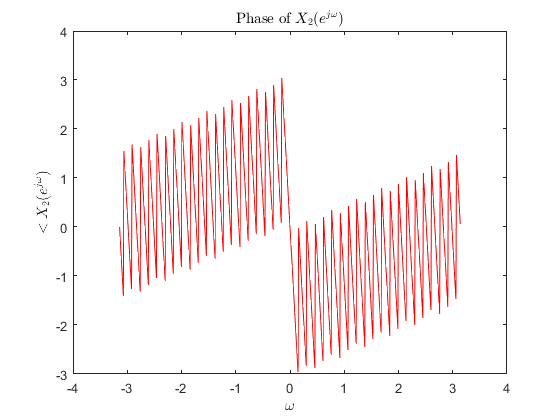

plot(w,angle(X2),'r');
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$<X_2(e^{j\omega})$','Interpreter','latex')
title ('Phase of $X_2(e^{j\omega})$','Interpreter','latex')

## 1.2)

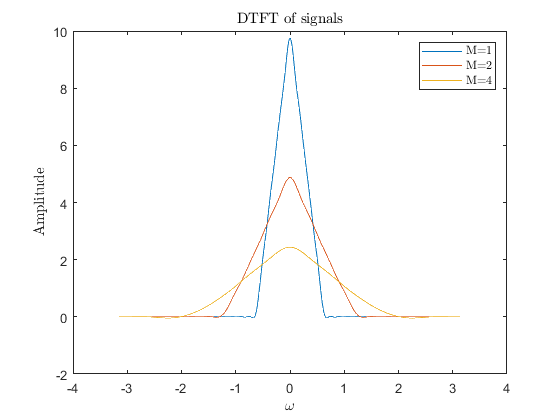

fs_con=100;
fs=10;
t=-4:1/fs_con:4;
n=-4*fs_con/fs+1:1:4*fs_con/fs;
xc=(sinc(t)).^2;
for k=1:length(n)
    xd(k)=xc(k*fs);
end
M=2;
y1=Compressor(xd,M);
n1=-4*fs_con/(M*fs)+1:1:4*fs_con/(M*fs);
M=4;
n2=-4*fs_con/(M*fs)+1:1:4*fs_con/(M*fs);
y2=Compressor(xd,M);
w=-pi:0.01:pi;
Y=DTFT(xd,n,w);
Y1=DTFT(y1,n1,w);
Y2=DTFT(y2,n2,w);
plot(w,real(Y));
hold on 
plot(w,real(Y1));
plot(w,real(Y2));
hold off
xlabel ('$\omega$','Interpreter','latex')
ylabel ('Amplitude','Interpreter','latex')
title ('DTFT of signals','Interpreter','latex')
legend('M=1','M=2','M=4','Interpreter','latex');

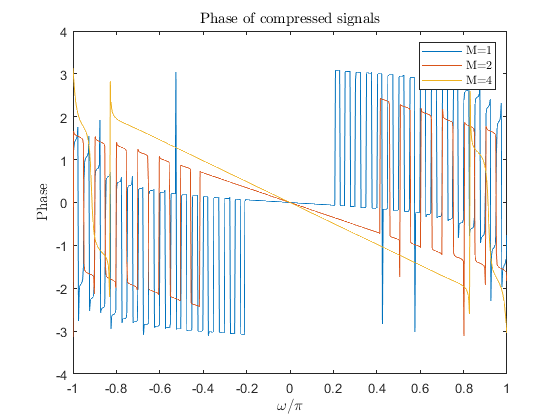

plot(w/pi,angle(Y));
hold on 
plot(w/pi,angle(Y1));
plot(w/pi,angle(Y2));
hold off
xlabel ('$\omega/\pi$','Interpreter','latex')
ylabel ('Phase','Interpreter','latex')
title ('Phase of compressed signals','Interpreter','latex')
legend('M=1','M=2','M=4','Interpreter','latex');

## 1.3)

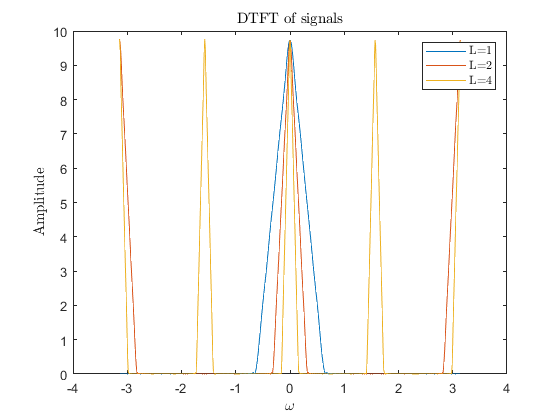

fs_con=100;
fs=10;
t=-4:1/fs_con:4;
n=-4*fs_con/fs+1:1:4*fs_con/fs;
xc=(sinc(t)).^2;
for k=1:length(n)
    xd(k)=xc(k*fs);
end
L=2;
y1=Expander(xd,L);
n1=-4*fs_con/fs*L+1:1:4*fs_con/fs*L;
L=4;
n2=-4*fs_con/fs*L+1:1:4*fs_con/fs*L;
y2=Expander(xd,L);
w=-pi:0.01:pi;
Y=DTFT(xd,n,w);
Y1=DTFT(y1,n1,w);
Y2=DTFT(y2,n2,w);
plot(w,abs(Y));
hold on 
plot(w,abs(Y1));
plot(w,abs(Y2));
hold off
xlabel ('$\omega$','Interpreter','latex')
ylabel ('Amplitude','Interpreter','latex')
title ('DTFT of signals','Interpreter','latex')
legend('L=1','L=2','L=4','Interpreter','latex');

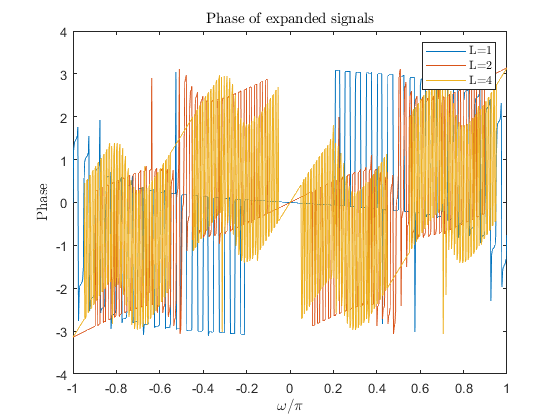

plot(w/pi,angle(Y));
hold on 
plot(w/pi,angle(Y1));
plot(w/pi,angle(Y2));
hold off
xlabel ('$\omega/\pi$','Interpreter','latex')
ylabel ('Phase','Interpreter','latex')
title ('Phase of expanded signals','Interpreter','latex')
legend('L=1','L=2','L=4','Interpreter','latex');

## 1.4)

### Plotting $s\left(t\right)$ and forming $s_d \left\lbrack n\right\rbrack$ by sampling with $F_s =20\mathrm{Hz}$

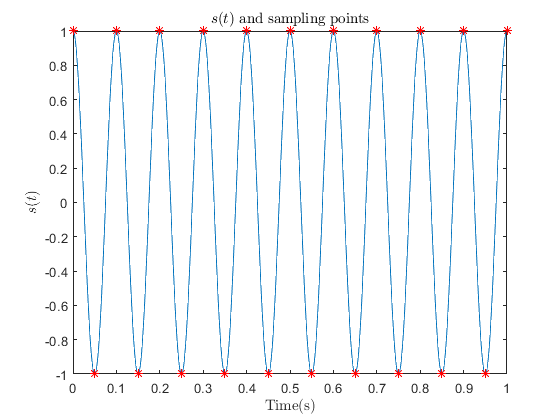

fs_con=1000;  fc=10;  Fs=20;
t=0:1/fs_con:1;
s=cos(2*pi*fc*t);
n=0:Fs;
sd(1)=s(1);
for k=2:length(n)
    sd(k)=s((k-1)*fs_con/Fs+1);
end
plot(t,s,n/(length(n)-1),sd,'r*');
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$s(t)$','Interpreter','latex')
title ('$s(t)$ and sampling points','Interpreter','latex')

### Plotting the DTFT of $s_d \left\lbrack n\right\rbrack$

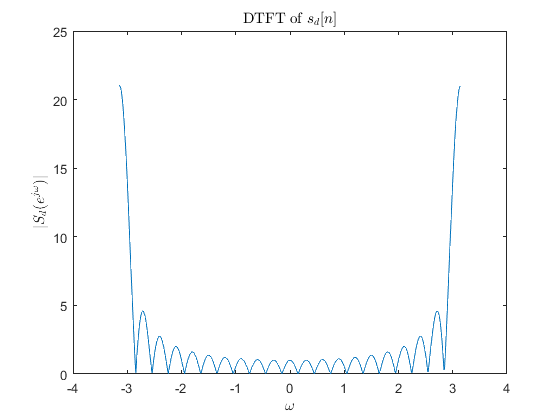

w=-pi:0.01:pi;
Sd=DTFT(sd,n,w);
plot(w,abs(Sd));
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$|S_d(e^{j\omega})|$','Interpreter','latex')
title ('DTFT of $s_d[n]$','Interpreter','latex')

### Forming $\hat{s} \left(t\right)$ with "Expander" and "Interpolate"

### Mode = 1

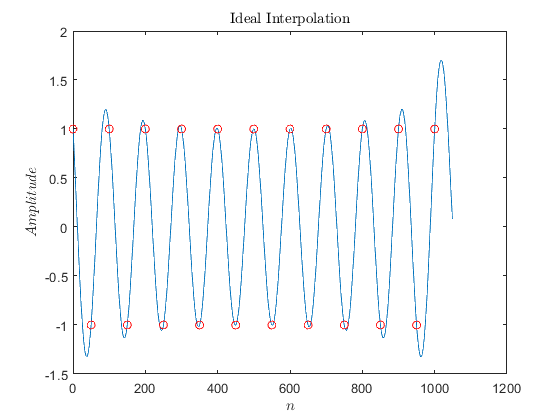

L=fs_con/Fs;
se=Expander(sd,L);
ne=0:1:length(n)*L-1;
s_hat1=Interpolate(se,ne,1,L,Fs);
plot(ne,s_hat1,n*L,sd,'ro')
xlabel ('$n$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Ideal Interpolation','Interpreter','latex')

### Mode = 2

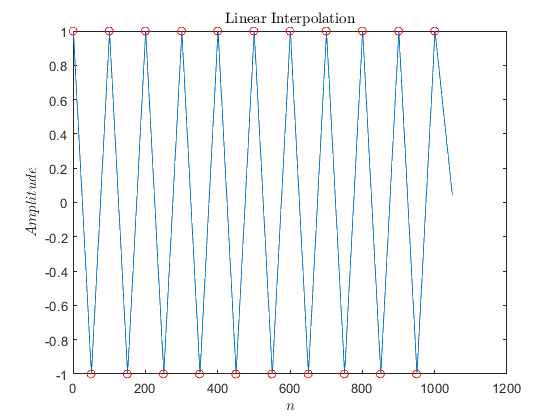

s_hat2=Interpolate(se,ne,2,L,Fs);
plot(ne,s_hat2,n*L,sd,'ro');
xlabel ('$n$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Linear Interpolation','Interpreter','latex')

### Mode = 3

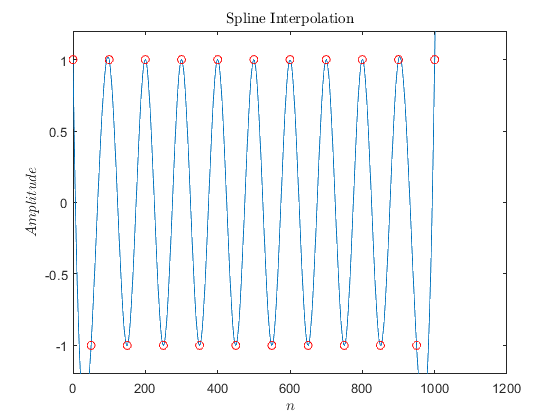

s_hat3=Interpolate(se,ne,3,L,Fs);
plot(ne,s_hat3,n*L,sd,'ro');
ylim([-1.2 1.2]);
xlabel ('$n$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Spline Interpolation','Interpreter','latex')

### MSE for Interpolations

t_=linspace(0,1,length(ne));
s_ref=cos(2*pi*fc*t_);
Error_ideal=immse(s_ref,s_hat1);
fprintf('Mean-squared error of Ideal Interpolation %0.7f',Error_ideal);

Mean-squared error of Ideal Interpolation 1.0625496

Error_linear=immse(s_ref,s_hat2);
fprintf('Mean-squared error of Linear Interpolation %0.7f',Error_linear);

Mean-squared error of Linear Interpolation 0.7619509

Error_spline=immse(s_ref,s_hat3);
fprintf('Mean-squared error of Spline Interpolation %0.7f',Error_spline);

Mean-squared error of Spline Interpolation 5.6390545

### Plotting $s\left(t\right)$ and forming $s_d \left\lbrack n\right\rbrack$ by sampling with $F_s =200\mathrm{Hz}$

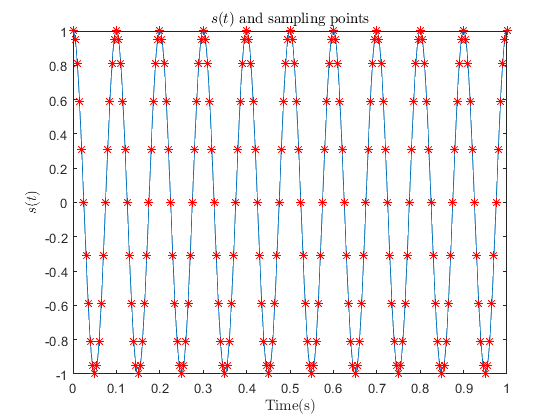

fs_con=1000;  fc=10;  Fs=200;
t=0:1/fs_con:1;
s=cos(2*pi*fc*t);
n=0:Fs;
sd(1)=s(1);
for k=2:length(n)
    sd(k)=s((k-1)*fs_con/Fs+1);
end
plot(t,s,n/(length(n)-1),sd,'r*');
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$s(t)$','Interpreter','latex')
title ('$s(t)$ and sampling points','Interpreter','latex')

### Plotting the DTFT of $s_d \left\lbrack n\right\rbrack$

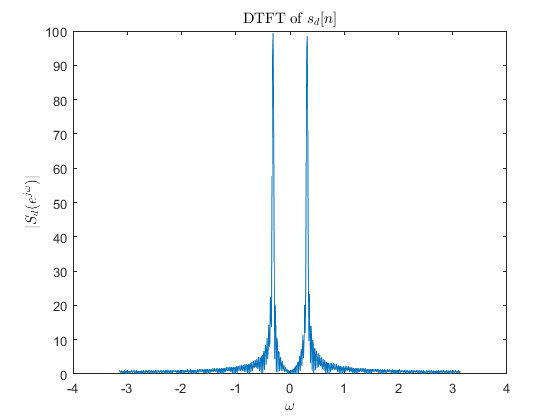

w=-pi:0.01:pi;
Sd=DTFT(sd,n,w);
plot(w,abs(Sd));
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$|S_d(e^{j\omega})|$','Interpreter','latex')
title ('DTFT of $s_d[n]$','Interpreter','latex')

### Forming $\hat{s} \left(t\right)$ with "Expander" and "Interpolate"

### Mode = 1

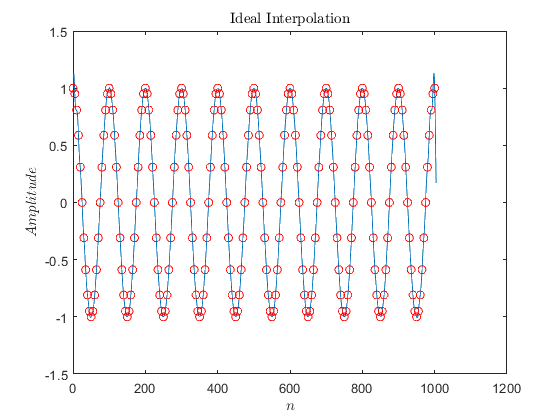

L=fs_con/Fs;
se=Expander(sd,L);
ne=0:1:length(n)*L-1;
s_hat1=Interpolate(se,ne,1,L,Fs);
plot(ne,s_hat1,n*L,sd,'ro')
xlabel ('$n$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Ideal Interpolation','Interpreter','latex')

### Mode = 2

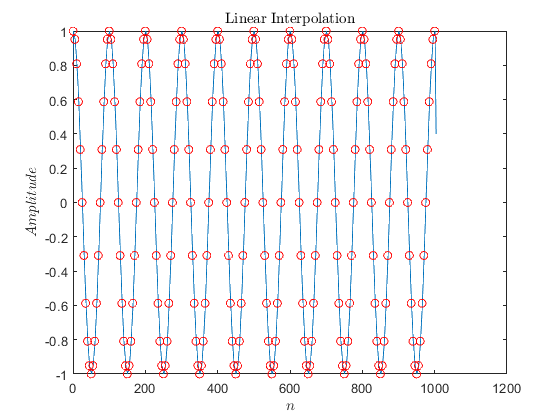

s_hat2=Interpolate(se,ne,2,L,Fs);
plot(ne,s_hat2,n*L,sd,'ro');
xlabel ('$n$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Linear Interpolation','Interpreter','latex')

### Mode = 3

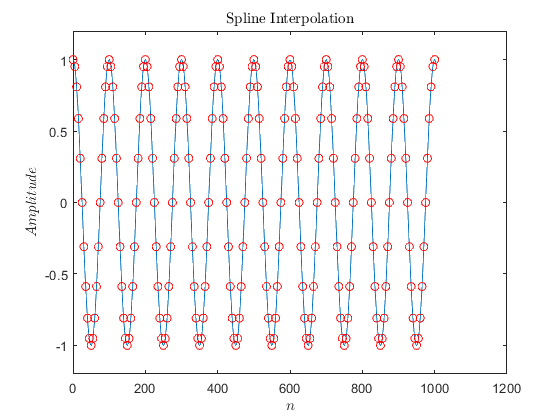

s_hat3=Interpolate(se,ne,3,L,Fs);
plot(ne,s_hat3,n*L,sd,'ro');
ylim([-1.2 1.2]);
xlabel ('$n$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Spline Interpolation','Interpreter','latex')

### MSE for Interpolations

t_=linspace(0,1,length(ne));
s_ref=cos(2*pi*fc*t_);
Error_ideal=immse(s_ref,s_hat1);
fprintf('Mean-squared error of Ideal Interpolation %0.7f',Error_ideal);

Mean-squared error of Ideal Interpolation 0.0118259

Error_linear=immse(s_ref,s_hat2);
fprintf('Mean-squared error of Linear Interpolation %0.7f',Error_linear);

Mean-squared error of Linear Interpolation 0.0051431

Error_spline=immse(s_ref,s_hat3);
fprintf('Mean-squared error of Spline Interpolation %0.7f',Error_spline);

Mean-squared error of Spline Interpolation 0.0104190

# **Functions **

## 1.1) DTFT

function [FT] = DTFT(x,n,w)
for m=1:length(w)
    FT(m)=sum(x.*exp(-1i*w(m)*n));
end
end

## 1.2) Compressor

function [y]=Compressor(x,M)
y=x(1:M:length(x));
end

## 1.3) Expander

function [y]=Expander(x,L)
y=zeros(1,length(x)*L);
y(1:L:length(y))=x;
end

## 1.4) Interpolate

function [y]=Interpolate(x,n,mode,L,fs)
n_=n(1:L:length(n))/L;  %% indexes before Expansion
xs=x(1:L:length(x));    %% values of signal before Expansion
t=n/(fs*L);
if mode==1    %% Ideal interpolation
    y=xs*sinc(ones(length(n_),1)*n/L-n_'*ones(1,length(n)));
end
if mode==2    %% Linear interpoltion
    for i=-L:L
        h_lin(i+L+1)=1-abs(i)/L;
    end
    y=conv(x,h_lin);
    y=y(L:length(y)-L-1);
end
if mode==3   %% spline interpolation
    y=spline(n_/fs,xs,t);
end
end